# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\John\Newstru\Newstru1\RawData'];    
Deci.SubjectList = 'gui';  
Deci.Step               = 1;
Deci.Proceed            = true;  
Deci.PCom               = false;                           % Activates Parallel Computing (if availible)
Deci.Folder.Version     = ['C:\Users\User\Desktop\John\Newstru\Newstru1\ProcessedData'];    

## 1. Trial Definitions

    Deci.DT.Type = 'Manual';             
    Deci.DT.Starts     = {9};         %Cell Array of Markers for ETs Start.
    Deci.DT.Ends       = {10};         %Cell Array of Markers for ETs End.
    Deci.DT.Markers    = {[20 21 23 24] [27 28] [31 32] [51 52]};   
    Deci.DT.Locks      = [14 30 50];
    Deci.DT.Toi        = [-2 3]; 
    
    Deci.DT.Block.Start = {11};
    Deci.DT.Block.End = {12};
    Deci.DT.Block.Markers = [];

## 2. PreProcessing Steps

Deci.PP.Demean              = [-.5 -.2];        % [Beg End], Secs Relative to .DT.Locks, Baseline Window for Correction.

## 3. Artifact Rejection

Deci.Art.crittoilim = [-.5 1.5]; 
Deci.Art.bpf = [1 80];

## 4. Analysis

#### General Set-Up

Deci.Analysis.Laplace            =true;                   % Leave .Laplace as 0 to not do a Laplacian Transformation based on file realistic_1005.txt format
Deci.Analysis.Locks = [1 2 3]; 
Deci.Analysis.DownSample = 500;

#### Time-Frequency Analysis

Deci.Analysis.Freq.method        = 'wavelet';    % Currently only uses Wavelet Decomp
Deci.Analysis.Freq.foi           = exp(linspace(log(4),log(40),20));       % Frequency of Interest
Deci.Analysis.Freq.width         = 7 ;           % Width
Deci.Analysis.Freq.gwidth        = 3;            % Gwidth
Deci.Analysis.Freq.Toi           = [-.5 1.5];       % Time Range
Deci.Analysis.Freq.Toilim        = [-2 3]; 

Deci.Analysis.Var =false;
Deci.Analysis.Clean = true;

## 5. Plotting

    Deci.Plot.Lock = '3';
    Deci.Plot.Conditions = {[20 31 51] [21 31 51] [23 31 51] [24 31 51] [20 31 52] [21 31 52] [23 31 52] [24 31 52] ...
                            [20 32 51] [21 32 51] [23 32 51] [24 32 51] [20 32 52] [21 32 52] [23 32 52] [24 32 52]};
    Deci.Plot.Var = false;
    Deci.Plot.GA = true;

#### Math

Deci.Plot.Math.Form = {'[x4+x2]/2','[x7+x5]/2','[x2+x5]/2','[x4+x7]/2' '[x17-x18]' '[x19-x20]'...
                       '[x2-x4]','[x5-x7]','[x4-x7]','[x2-x5]' '[[x2+x3+x4+x13+x14+x15]/6]' '[[x5+x6+x7+x10+x11+x12]/6]' '[x27-x28]'};   
%Deci.Plot.Math.Type = 0;


#### Conditions

Deci.Plot.Draw = {[2:7] [17:18] [19:20] [21:22] [23:24] [25] [26] [27:28] [29]};
Deci.Plot.Title = {'All Opt trials' 'Prediction Error' 'Valence Signals' 'Valence-independent Prediction Error' 'PE-independent Valence Signals' ...
                    'Valence-Dependent Prediction Error' 'PE-dependent Valence Signal' 'Expectation Signals' 'Expectation Subtraction'};
Deci.Plot.Subtitle = {{'+R' '+0' '+P' '-R' '-0' '-P'} {'+' '-'} {'R' 'P'} {'+R - +P' '-R - -P'} {'+P - -P' '+R - -R'} {'+ - -'} {'R - P'} {'[BTEOpt+WTEWor]' '[WTEOpt+BTEWor]'} {'[BTEOpt+WTEWor]-[WTEOpt+BTEWor]'}};
Deci.Plot.Figures = [true true true false false false false false false];

#### Time-Frequency

%Deci.Plot.Freq.Foi = [];
Deci.Plot.Freq.Foi = [4 8];
Deci.Plot.Freq.Toi = [0 .8];
Deci.Plot.Freq.Channel = ['Reinhart-All'];
Deci.Plot.Freq.Type = 'TotalPower';     % Use 'TotalPower','ITPC' or 'EvokedPower'

Deci.Plot.Freq.Bsl = [-.5 -.2];           % Baseline Correction Time
Deci.Plot.Freq.Roi = 'maxmin';          % use 'maxmin','maxabs or [min max] to set.
Deci.Plot.Freq.BslType ='db';    % Use 'absolute','relative','relchange','db','normchange'

Deci.Plot.Freq.Topo =1;
Deci.Plot.Freq.Square =1;

Deci.Plot.Freq.Wires.avg =  'freq';


#### Behavioral

Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';

Deci.Plot.Behv.Acc.Total = {[1:16] [1:16]};
Deci.Plot.Behv.Acc.Subtotal = {[1:8] [9:16]};
Deci.Plot.Behv.Acc.Title = ['All Trials Percent'];
Deci.Plot.Behv.Acc.Subtitle = {'Opt Percent' 'Wst Percent'};

Deci.Plot.Behv.Acc.Block = [1:6];
Deci.Plot.Behv.Acc.Collapse.Trial =false;
Deci.Plot.Behv.Acc.Collapse.Block = true;
Deci.Plot.Behv.Acc.Collapse.Subject = false;
Deci.Plot.Behv.Acc.Collapse.Uneven = 'maxlength:nans';
Deci.Plot.Behv.Acc.Collapse.Movmean =  true;

Deci.Plot.Behv.RT.Draw = {[1:8] [9:16]};
Deci.Plot.Behv.RT.Title = ['All Trials RT'];
Deci.Plot.Behv.RT.Subtitle = {'Opt' 'Worst'};
Deci.Plot.Behv.RT.Locks = [1 2];

Deci.Plot.Behv.RT.Block = [1:6];
Deci.Plot.Behv.RT.Collapse.Trial =false;
Deci.Plot.Behv.RT.Collapse.Block = true;
Deci.Plot.Behv.RT.Collapse.Subject = false;
Deci.Plot.Behv.RT.Collapse.Uneven = 'maxlength:nans';

Options

Deci.Run.Behavior = false;
Deci.Run.Freq =true;
Deci.Run.ERP =false;
Deci.Run.CFC = false;

## ** 6. Run**

----------------------
Starting DefineTrialor
Found 480 trials for Instru_EEG_014
Saving Preprocessing Data
Finished DefineTrial at 1.4202
----------------------
----------------------
Starting PreProcessor for Instru_EEG_014
Implicit Rereference
Ocular Rereference
Highbandpass Filter
Baseline Correction
Saving Preprocessing Data
Finished PreProcessor at 96.714
----------------------
----------------------
Starting Artifactor


searching for artifacts in 62 channels
searching in trial 480 from 480



detected 146 artifacts
the call to "ft_artifact_zvalue" took 94 seconds


searching for artifacts in 4 channels
searching in trial 480 from 480



detected 113 artifacts
the call to "ft_artifact_zvalue" took 14 seconds
detected 146 muscle artifacts
detected 113 eog artifacts
rejected   87 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
retained   43 trials with artifacts outside critical window
resulting 393 trials
the input is raw data with 62 channels and 480 trials


the call to "ft_redefinetrial" took 9 seconds
the call to "ft_rejectartifact" took 10 seconds
the input is raw data with 62 channels and 393 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the input is raw data with 62 channels and 393 trials


showing a summary of the data for all channels and trials


computing metric [--|                                                      ]computing metric [------/                                                  ]computing metric [------------                                             ]computing metric [----------------\                                        ]computing metric [----------------------|                                  ]computing metric [---------------------------/                             ]computing metric [---------------------------------                        ]computing metric [--------------------------------------\                  ]computing metric [-------------------------------------------|             ]computing metric [-------------------------------------------------/       ]computing metric [-------------------------------------------------------- ]computing metric [--------------------------------------------------------\]


380 trials marked as GOOD, 13 trials marked as BAD
62 channels marked as GOOD, 0 channels marked as BAD
the following trials were removed: 5, 82, 116, 129, 141, 153, 273, 285, 304, 312, 332, 386, 389


the call to "ft_rejectvisual" took 1971 seconds
the input is raw data with 62 channels and 380 trials


baseline correcting data 
scaling data with 1 over 132.443684
concatenating data............................................................................................................................................................................................................................................................................................................................................................................................
concatenated data matrix size 62x1868393
starting decomposition using runica

Input data size [20,1868393] = 20 channels, 1868393 frames/nAfter PCA dimension reduction,
  finding 20 ICA components using logistic ICA.
Decomposing 4670 frames per ICA weight ((400)^2 = 1868393 weights, Initial learning rate will be 0.001, block size 73.
Learning rate will be multiplied by 0.9 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias ad

baseline correcting data 
scaling data with 1 over 108.731779
not concatenating data
starting decomposition using predetermined unmixing matrix
not applying the backprojection matrix to the sensor description
the call to "ft_componentanalysis" took 5 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds


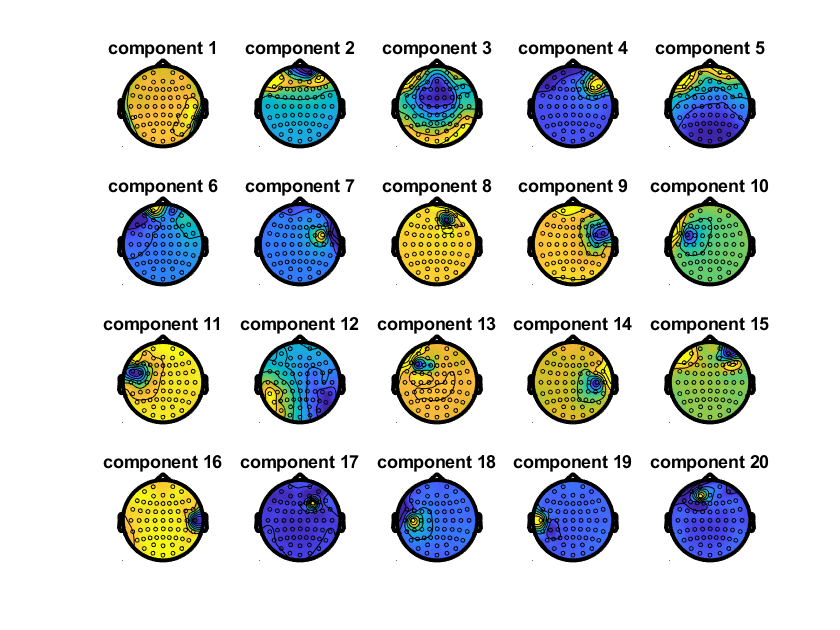

the call to "ft_topoplotIC" took 7 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the input is component data with 20 components and 62 original channels
the input is raw data with 20 channels and 480 trials
detected   0 visual artifacts


Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn.



removing 3 components
keeping 17 components
not applying the backprojection matrix to the sensor description
the call to "ft_rejectcomponent" took 1 seconds


detected 148 artifacts
the call to "ft_artifact_zvalue" took 91 seconds


detected 149 artifacts
the call to "ft_artifact_zvalue" took 14 seconds
detected 148 muscle artifacts
detected 149 eog artifacts
rejected   74 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
retained   41 trials with artifacts outside critical window
resulting 406 trials
the input is raw data with 62 channels and 480 trials


the call to "ft_redefinetrial" took 9 seconds
the call to "ft_rejectartifact" took 9 seconds
the input is raw data with 62 channels and 406 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the input is raw data with 62 channels and 406 trials


showing a summary of the data for all channels and trials


computing metric [-----|                                                   ]computing metric [----------/                                              ]computing metric [-----------------                                        ]computing metric [----------------------\                                  ]computing metric [---------------------------|                             ]computing metric [---------------------------------/                       ]computing metric [----------------------------------------                 ]computing metric [---------------------------------------------\           ]computing metric [---------------------------------------------------|     ]computing metric [--------------------------------------------------------/]


395 trials marked as GOOD, 11 trials marked as BAD
4 channels marked as GOOD, 58 channels marked as BAD
no channels were removed from the data
the following trials were removed: 108, 110, 118, 143, 242, 243, 259, 312, 319, 344, 398


the call to "ft_rejectvisual" took 2597 seconds


the input is raw data with 62 channels and 395 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the input is raw data with 62 channels and 395 trials


showing a summary of the data for all channels and trials


computing metric [----|                                                    ]computing metric [---------/                                               ]computing metric [----------------                                         ]computing metric [--------------------\                                    ]computing metric [--------------------------|                              ]computing metric [------------------------------/                          ]computing metric [------------------------------------                     ]computing metric [-----------------------------------------\               ]computing metric [----------------------------------------------|          ]computing metric [----------------------------------------------------/    ]computing metric [---------------------------------------------------------]


383 trials marked as GOOD, 12 trials marked as BAD
62 channels marked as GOOD, 0 channels marked as BAD
the following trials were removed: 102, 128, 138, 236, 273, 285, 305, 336, 347, 373, 386, 389


the call to "ft_rejectvisual" took 39 seconds


Finished Artifactor at 8612.5187
----------------------
the input is raw data with 62 channels and 383 trials


using electrodes specified in the configuration
computing SCD for trial 383 of 383



output surface laplacian is in uV/m^2
the call to "ft_scalpcurrentdensity" took 33 seconds
the input is raw data with 60 channels and 383 trials
resampling data
resampling data in trial 383 from 383

original sampling rate = 1000 Hz
new sampling rate = 500 Hz
the call to "ft_resampledata" took 13 seconds
the input is raw data with 60 channels and 383 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 60 channels and 383 trials


processing trials
trial 383, frequency 20 (39.98 Hz)

the call to "ft_freqanalysis" took 195 seconds


preprocessing
preprocessing trial 383 from 383

the call to "ft_preprocessing" took 1 seconds
searching for artifacts in 60 channels
searching in trial 383 from 383

detected 5 artifacts
the call to "ft_artifact_abszvalue" took 1 seconds
preprocessing
preprocessing trial 383 from 383

the call to "ft_preprocessing" took 1 seconds
searching for artifacts in 20 channels
searching in trial 383 from 383

detected 0 artifacts
the call to "ft_artifact_abszvalue" took 1 seconds
detected   5 muscle artifacts
detected   0 eog artifacts
rejected    4 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
resulting 379 trials
the input is raw data with 20 channels and 383 trials
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_rejectartifact" took 0 seconds


Elapsed time is 217.251001 seconds.
the input is raw data with 60 channels and 383 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 60 channels and 383 trials


processing trials
trial 383, frequency 20 (39.98 Hz)

the call to "ft_freqanalysis" took 194 seconds


preprocessing
preprocessing trial 383 from 383

the call to "ft_preprocessing" took 1 seconds
searching for artifacts in 60 channels
searching in trial 383 from 383

detected 9 artifacts
the call to "ft_artifact_abszvalue" took 1 seconds
preprocessing
preprocessing trial 383 from 383

the call to "ft_preprocessing" took 1 seconds
searching for artifacts in 20 channels
searching in trial 383 from 383

detected 0 artifacts
the call to "ft_artifact_abszvalue" took 1 seconds
detected   9 muscle artifacts
detected   0 eog artifacts
rejected    8 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
resulting 375 trials
the input is raw data with 20 channels and 383 trials
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_rejectartifact" took 0 seconds


Elapsed time is 216.064119 seconds.
the input is raw data with 60 channels and 383 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 60 channels and 383 trials


processing trials
trial 383, frequency 20 (39.98 Hz)

the call to "ft_freqanalysis" took 196 seconds


preprocessing
preprocessing trial 383 from 383

the call to "ft_preprocessing" took 1 seconds
searching for artifacts in 60 channels
searching in trial 383 from 383

detected 10 artifacts
the call to "ft_artifact_abszvalue" took 1 seconds
preprocessing
preprocessing trial 383 from 383

the call to "ft_preprocessing" took 1 seconds
searching for artifacts in 20 channels
searching in trial 383 from 383

detected 1 artifacts
the call to "ft_artifact_abszvalue" took 1 seconds
detected  10 muscle artifacts
detected   1 eog artifacts
rejected    9 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
resulting 374 trials
the input is raw data with 20 channels and 383 trials
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_rejectartifact" took 0 seconds


Elapsed time is 209.470826 seconds.


Channel AF3 of 60
Channel AF4 of 60
Channel AF7 of 60
Channel AF8 of 60
Channel AFz of 60
Channel C1 of 60
Channel C2 of 60
Channel C3 of 60
Channel C4 of 60
Channel C5 of 60
Channel C6 of 60
Channel CP1 of 60
Channel CP2 of 60
Channel CP3 of 60
Channel CP4 of 60
Channel CP5 of 60
Channel CP6 of 60
Channel CPz of 60
Channel Cz of 60
Channel F1 of 60
Channel F2 of 60
Channel F3 of 60
Channel F4 of 60
Channel F5 of 60
Channel F6 of 60
Channel F7 of 60
Channel F8 of 60
Channel FC1 of 60
Channel FC2 of 60
Channel FC3 of 60
Channel FC4 of 60
Channel FC5 of 60
Channel FC6 of 60
Channel FCz of 60
Channel FT7 of 60
Channel FT8 of 60
Channel Fz of 60
Channel O1 of 60
Channel O2 of 60
Channel Oz of 60
Channel P1 of 60
Channel P2 of 60
Channel P3 of 60
Channel P4 of 60
Channel P5 of 60
Channel P6 of 60
Channel P7 of 60
Channel P8 of 60
Channel PO3 of 60
Channel PO4 of 60
Channel PO7 of 60
Channel PO8 of 60
Channel POz of 60
Channel Pz of 60
Channel T7 of 60
Channel T8 of 60
Channel TP10 of 60
Cha

the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 1 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 1 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 1 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 1 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 1 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 1 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 1 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 1 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 1 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 1 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 1 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 1 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 1 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 1 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 1 subjects


the call to "ft_freqgrandaverage" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 se

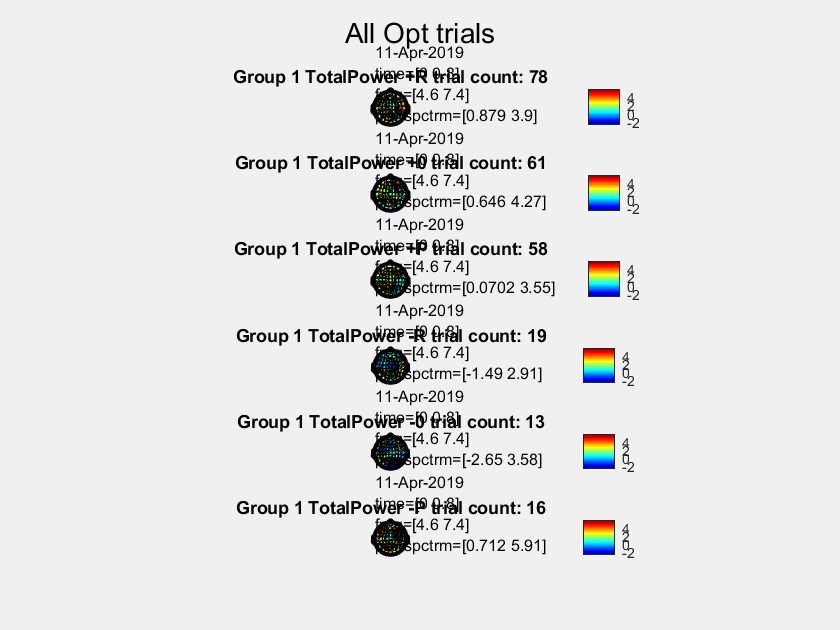

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


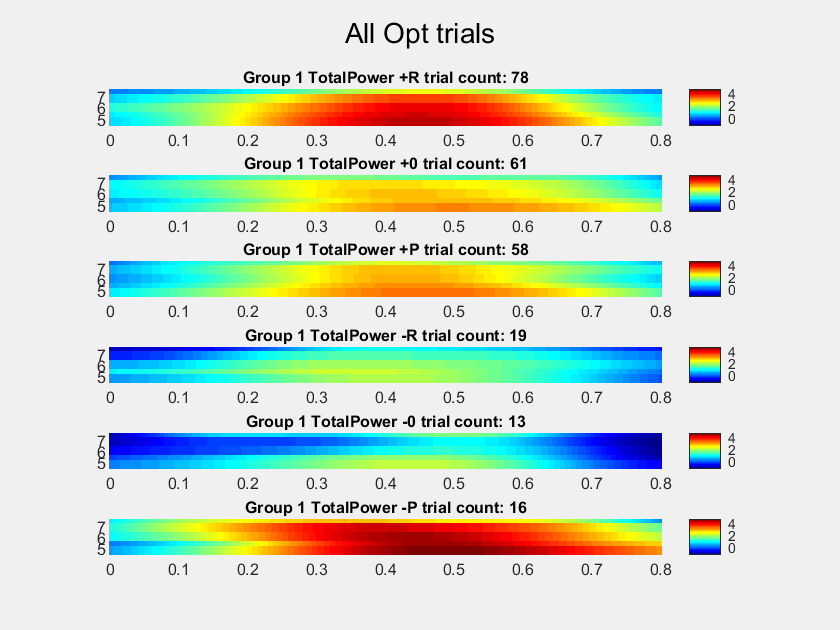

the call to "ft_singleplotTFR" took 0 seconds


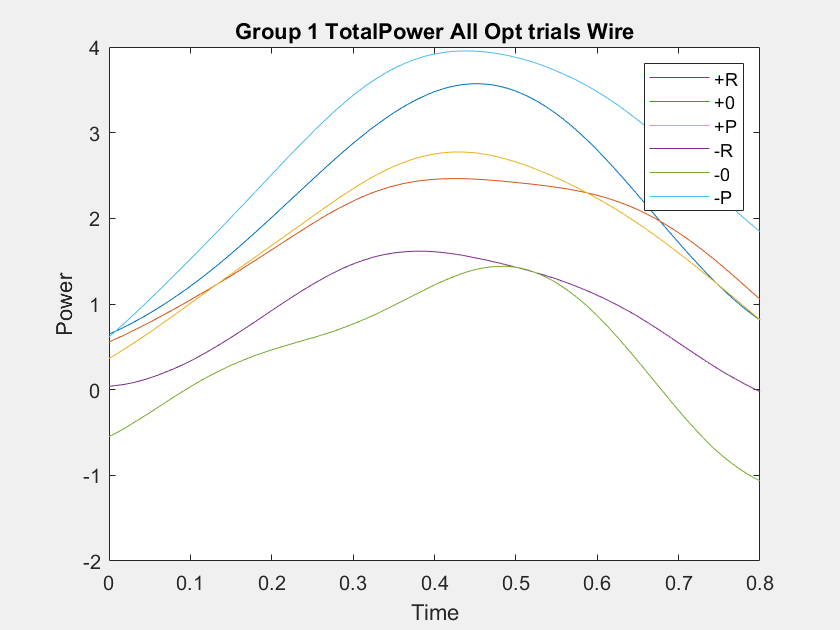

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


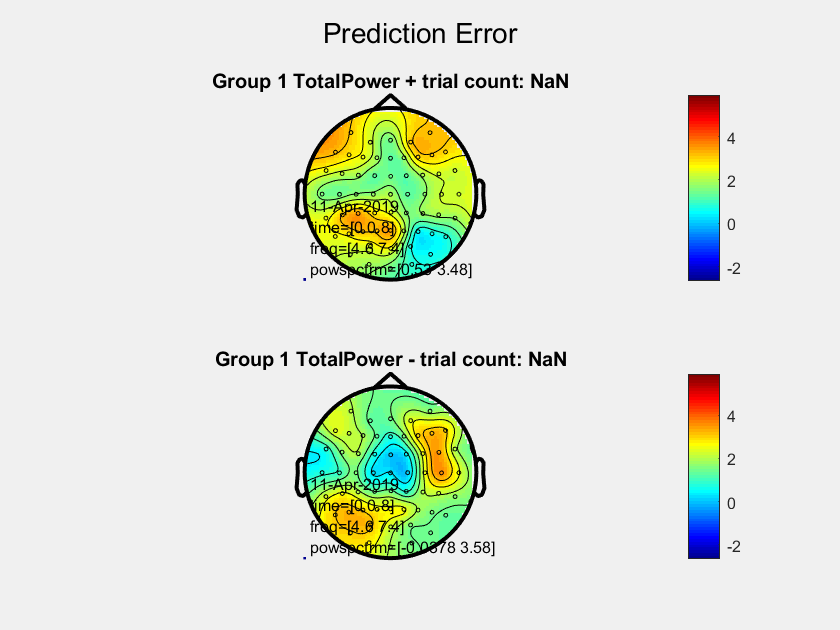

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


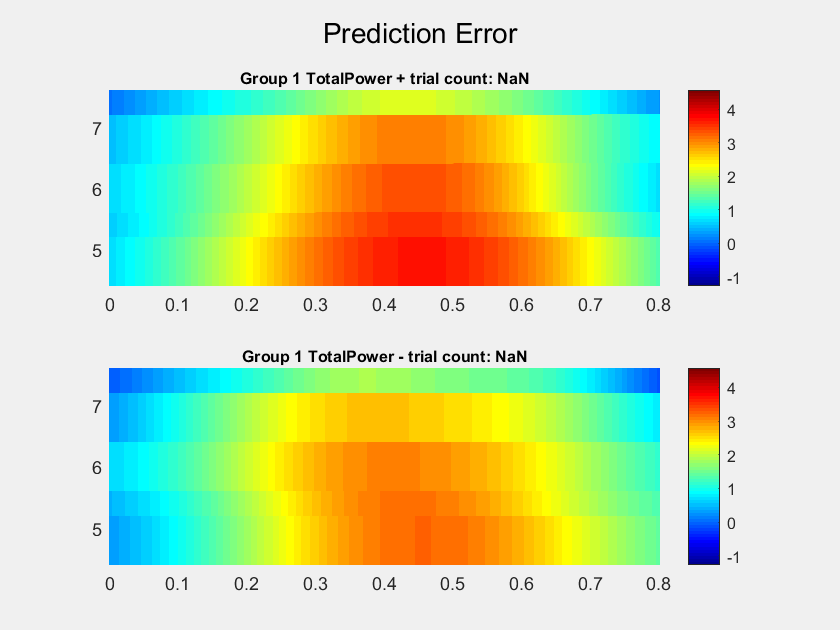

the call to "ft_singleplotTFR" took 0 seconds


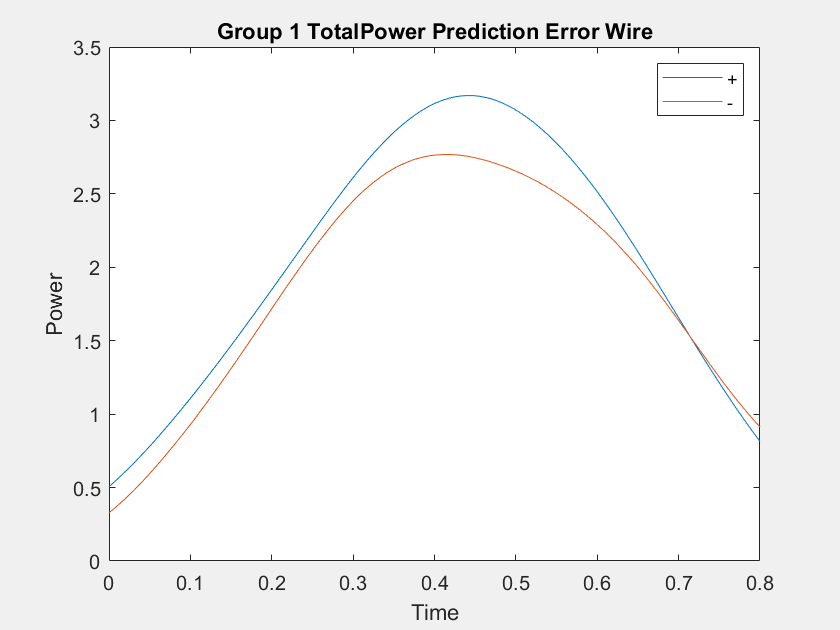

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


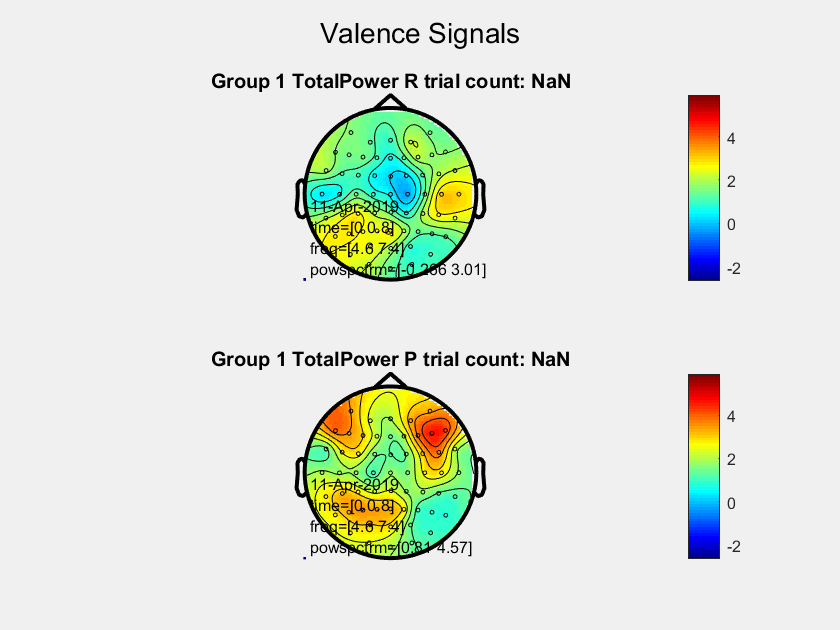

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


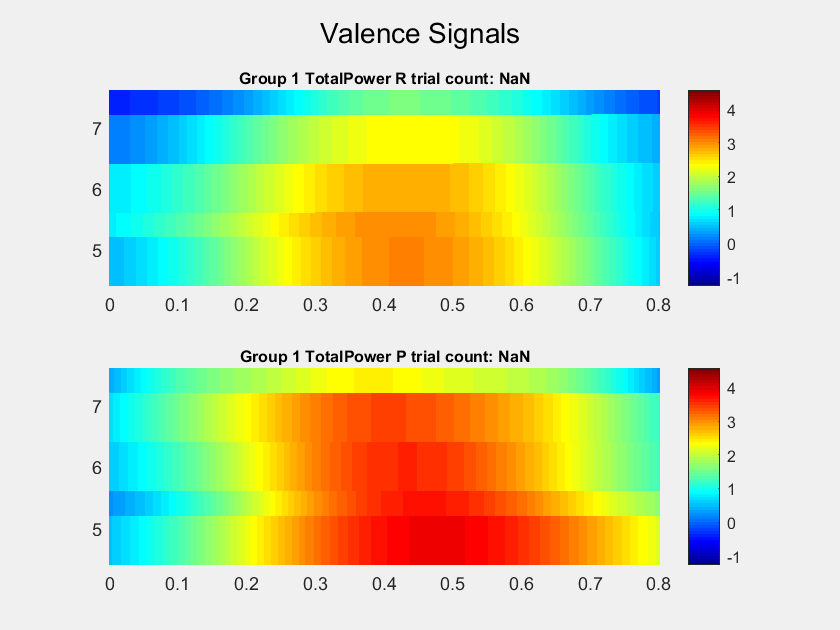

the call to "ft_singleplotTFR" took 0 seconds


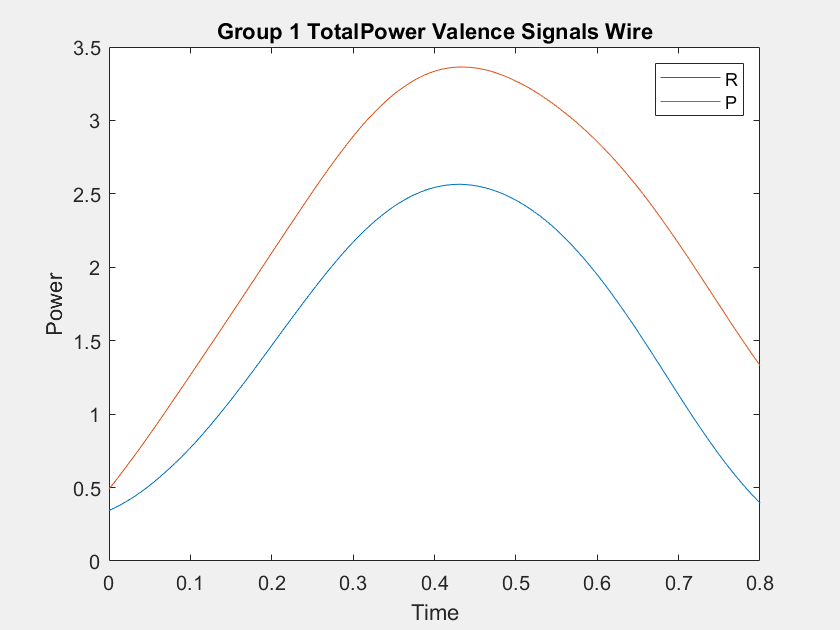

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds



Deci_Backend(Deci);